For the continuous version

%load('smilefrown1filt0p5notch56t64.mat')
load('run15filt0p5doublenotch56t64a120.mat')

EEG.timessec = EEG.times./1000; %version of times in seconds, useful for signal processing

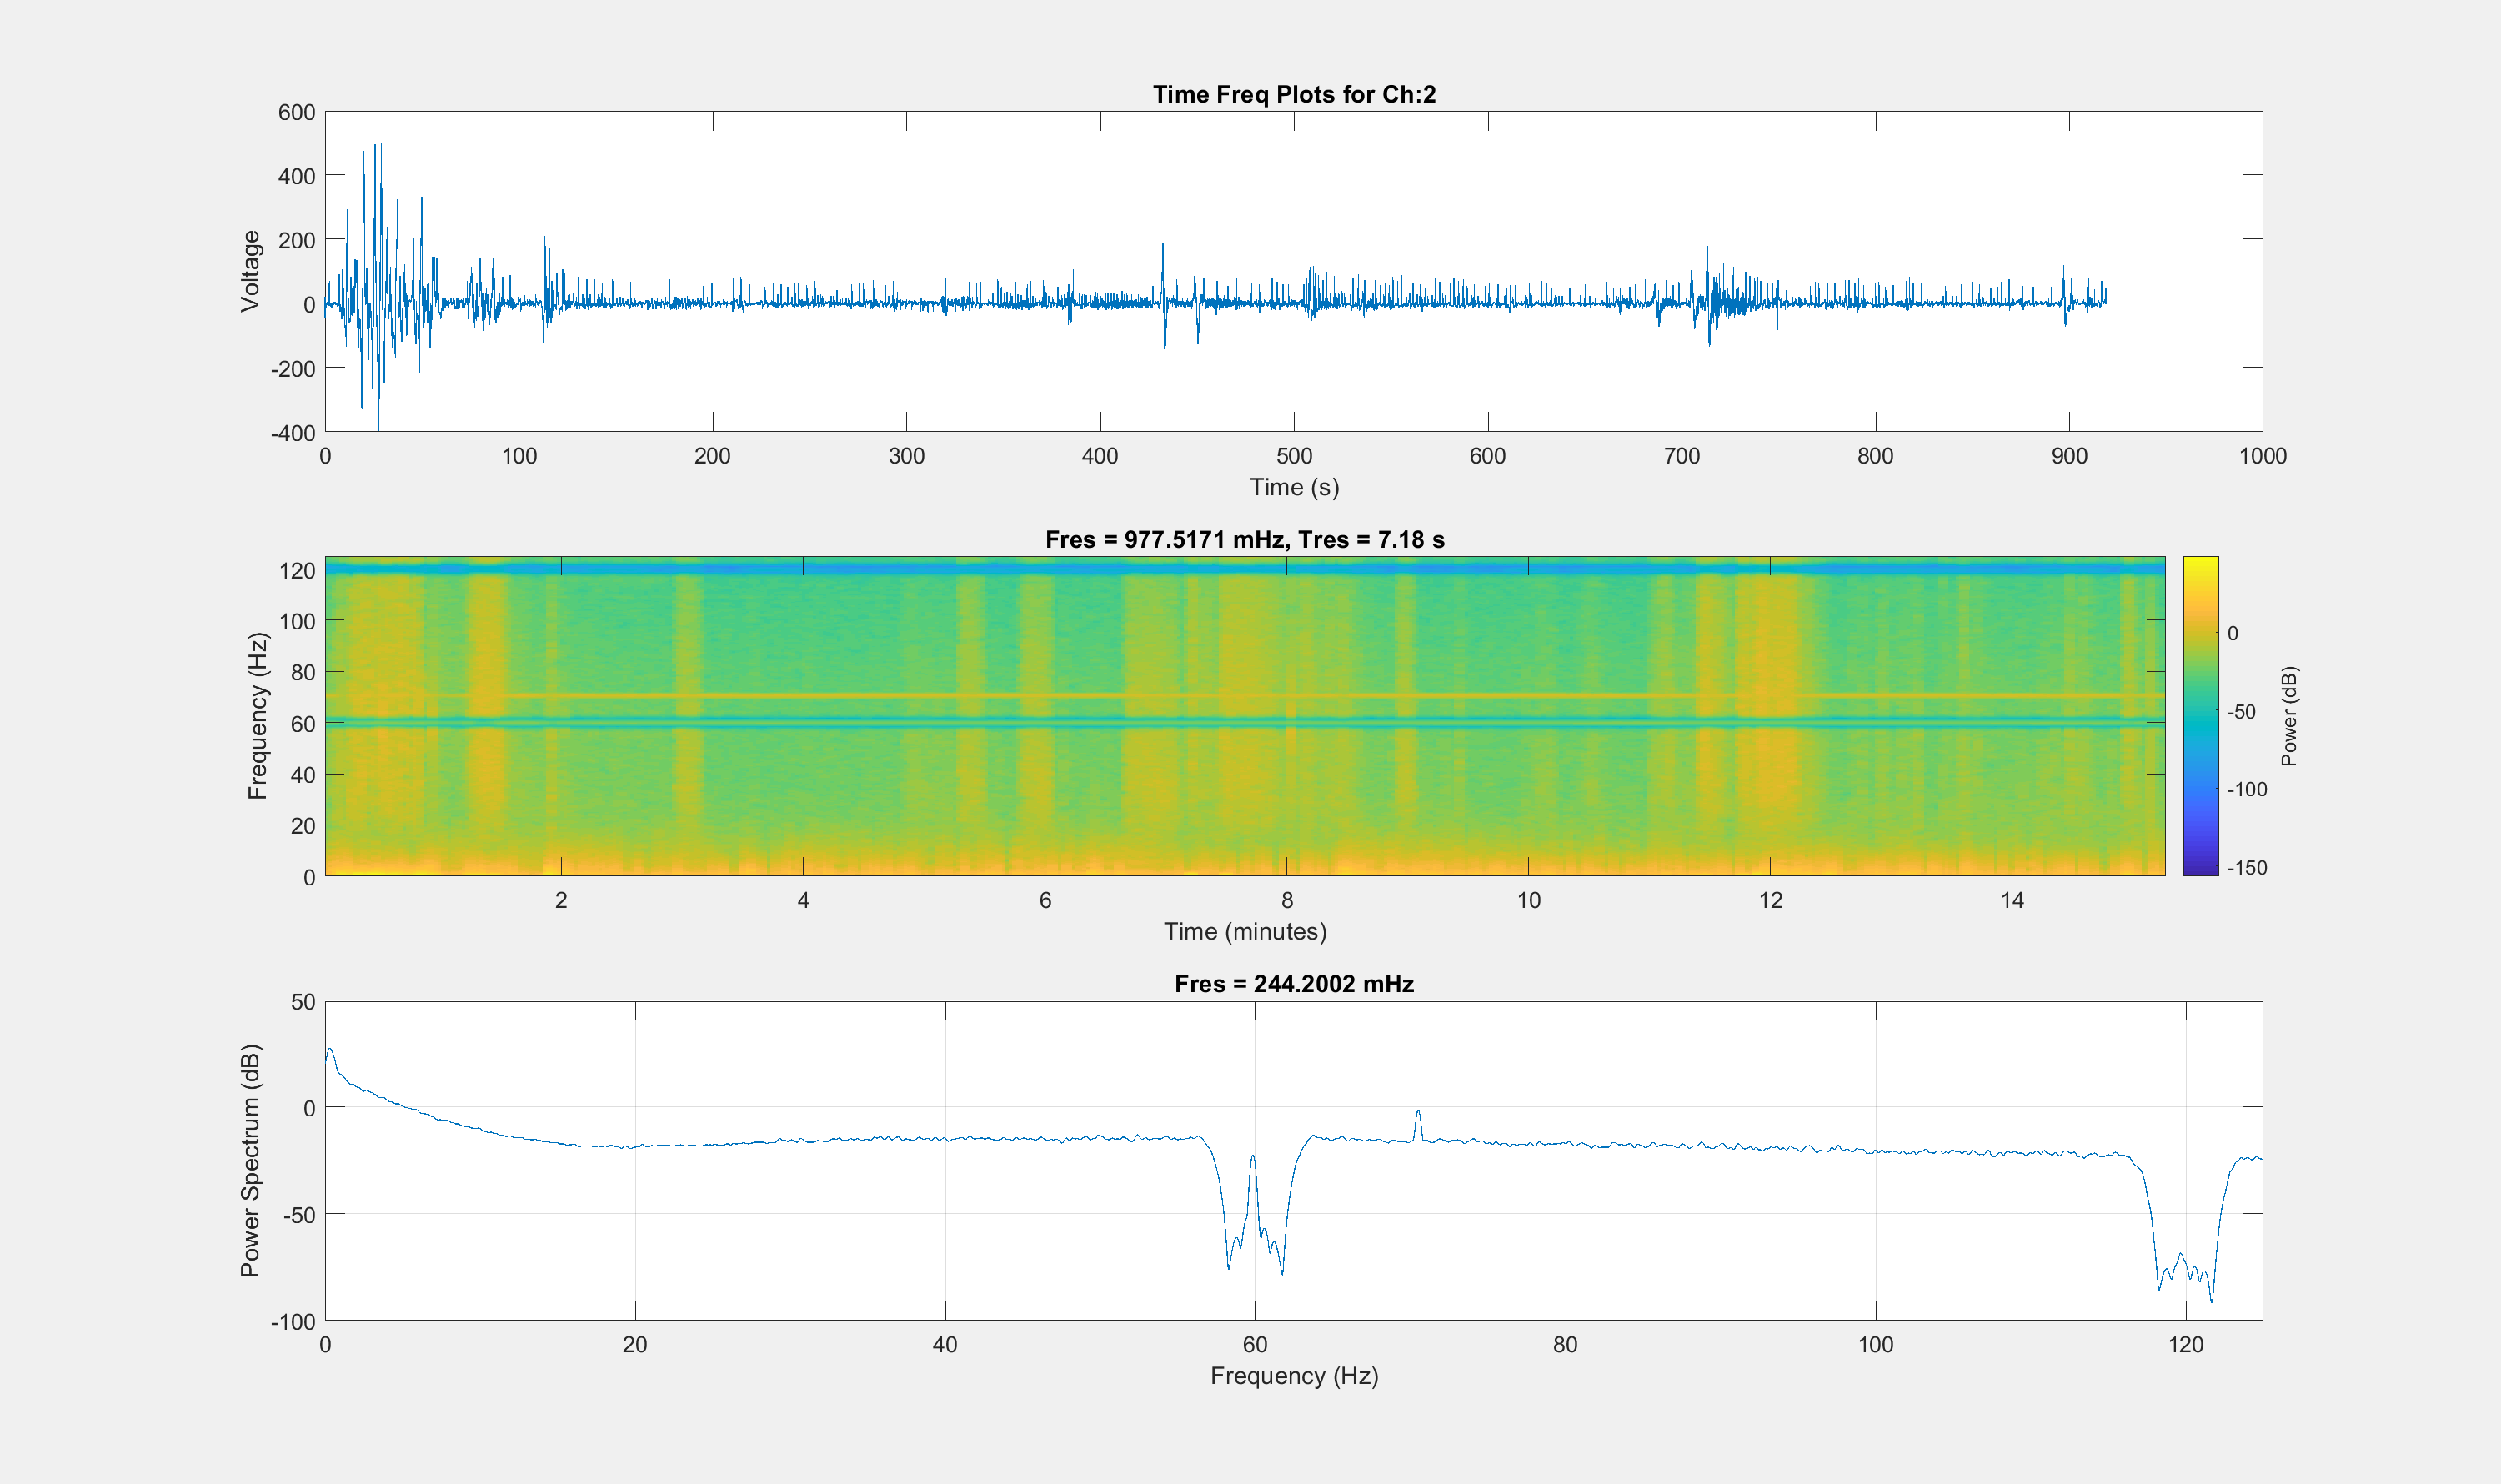

channel = 2;
figure
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
subplot(3,1,1)
plot(EEG.timessec, EEG.data(channel,:)); ylabel('Voltage'); xlabel('Time (s)');
title(strcat('Time Freq Plots for Ch: ', num2str(channel)));
subplot(3,1,2)
pspectrum(EEG.data(channel,:),EEG.timessec,'spectrogram'); 
subplot(3,1,3)
pspectrum(EEG.data(channel,:),EEG.timessec); 
hold off;

Use a continuous wavelet transform to get a deeper view

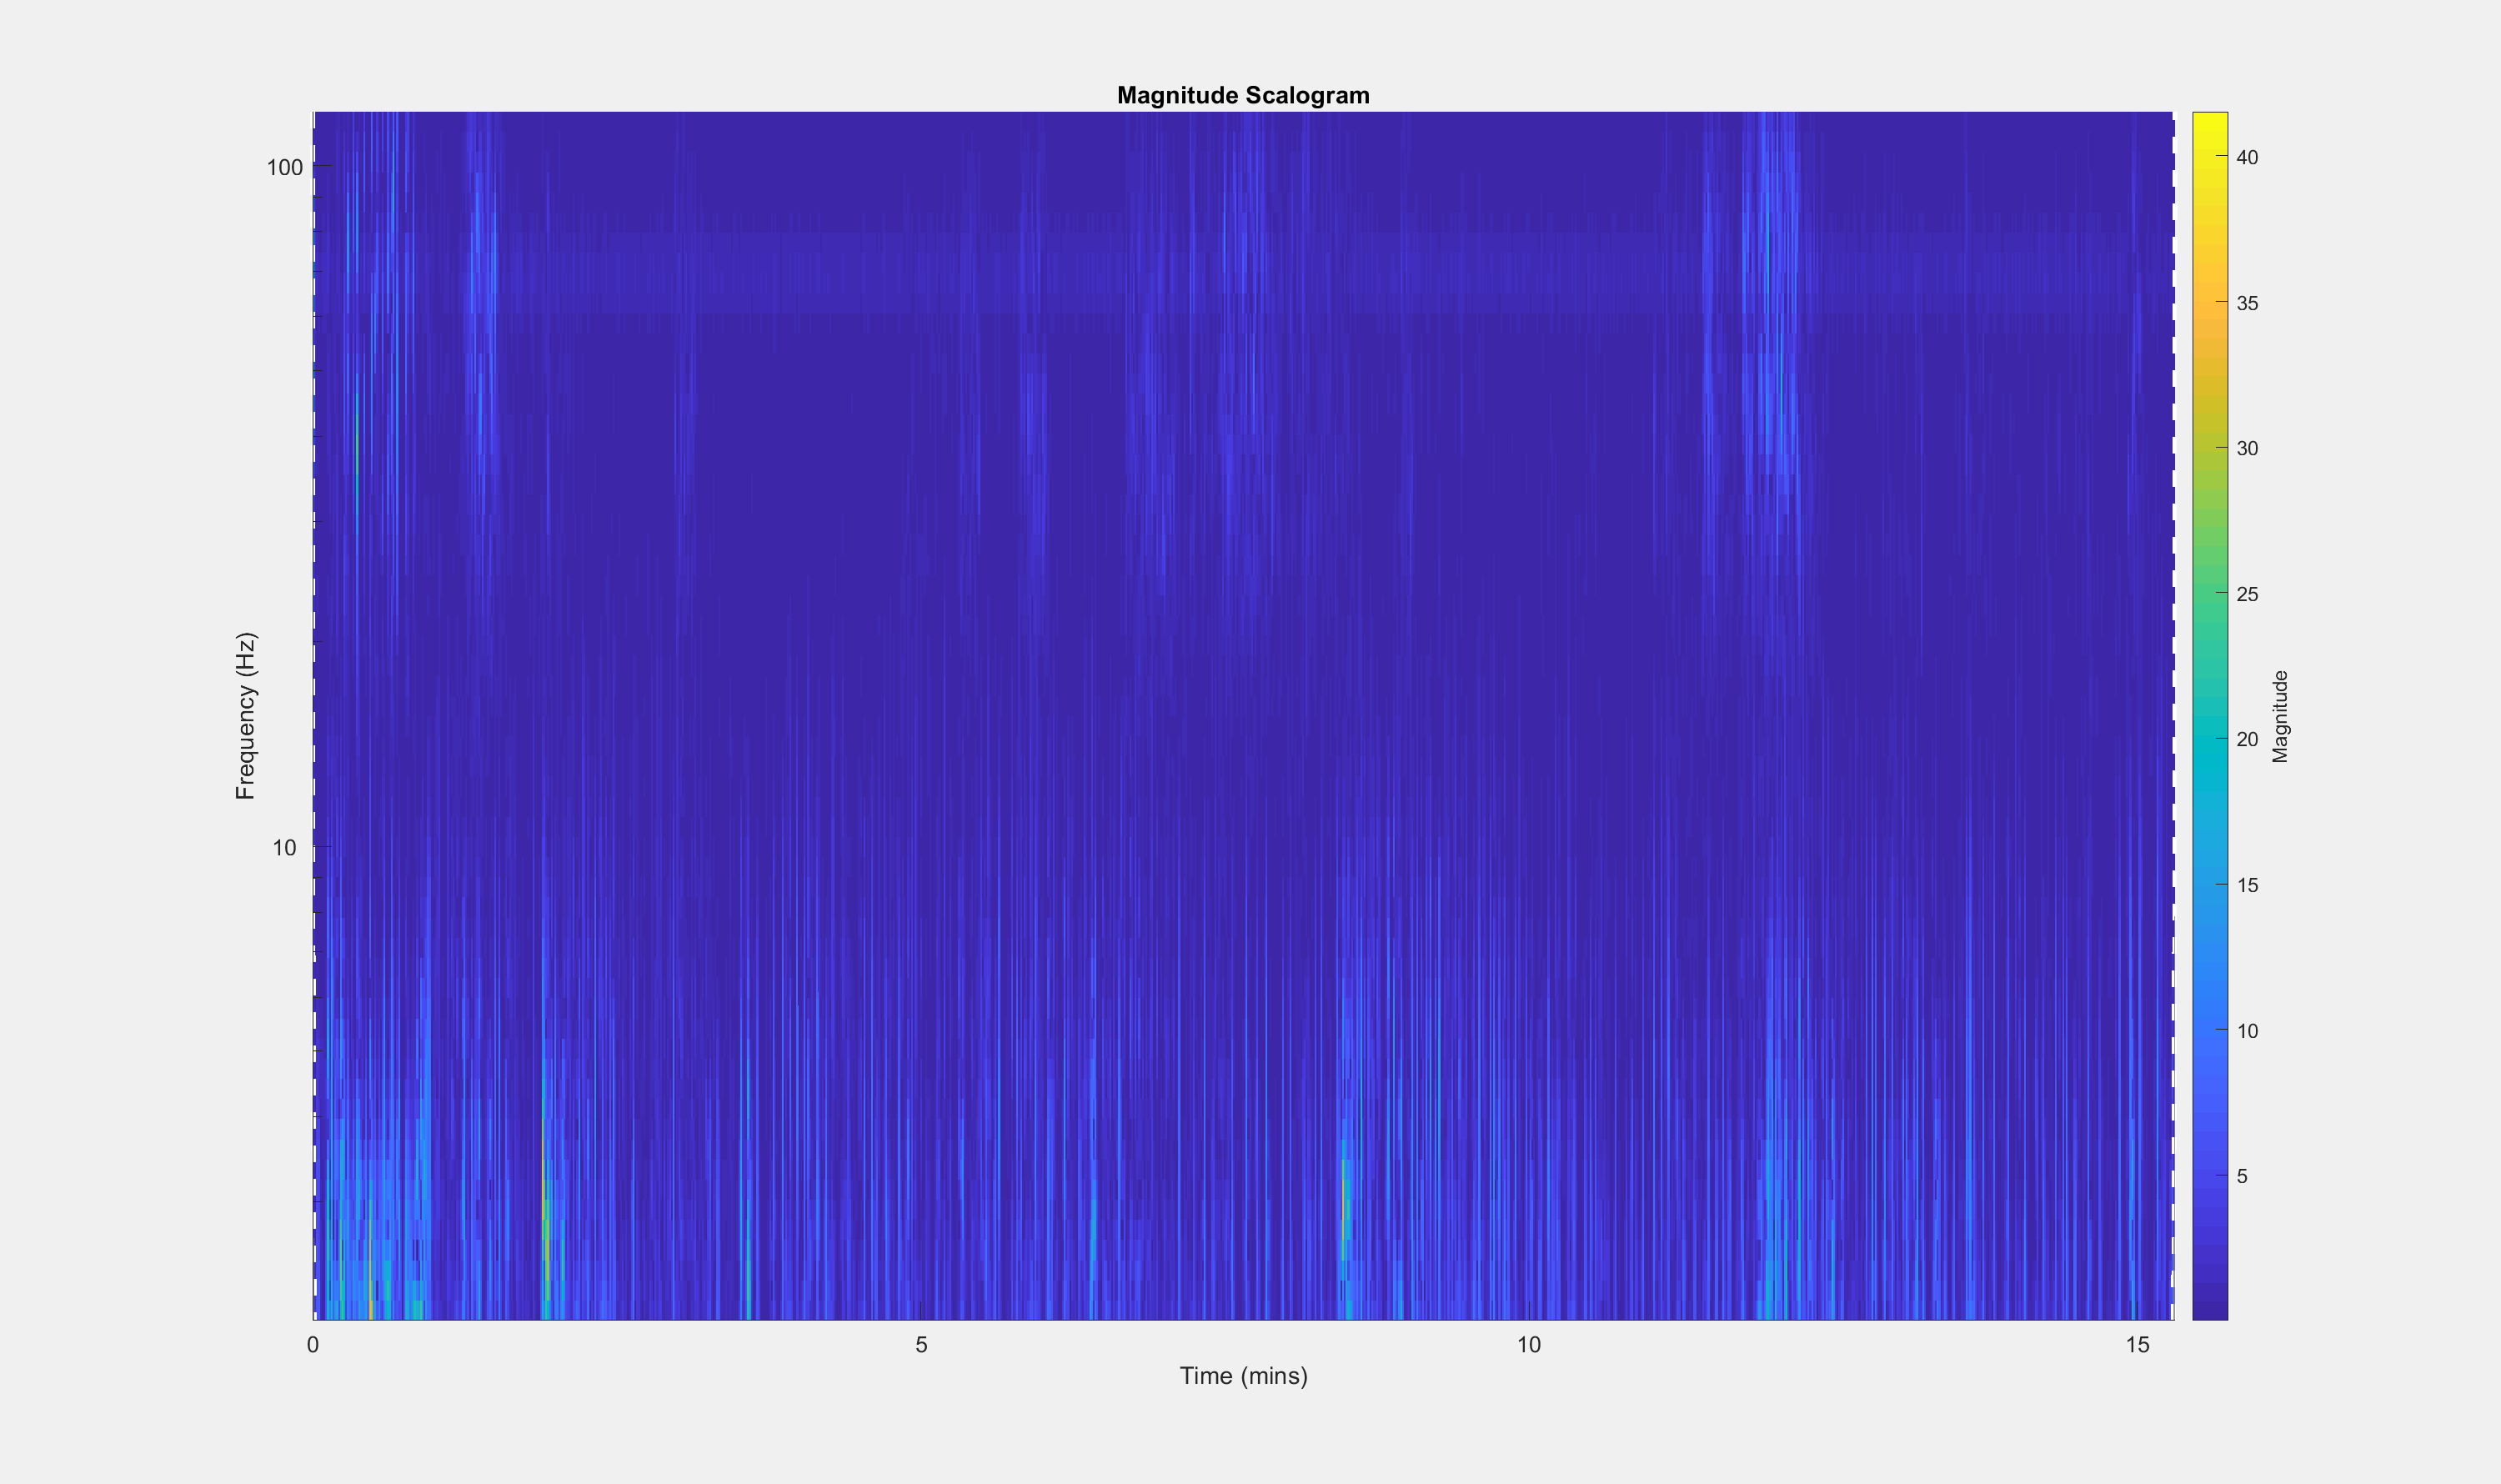

figure;
set(gcf,'Visible','on','WindowState','maximized','Name',strcat('Ch: ', num2str(channel))) % This pops out the figure for easier viewing
cwt(double(EEG.data(channel,:)),EEG.srate,'FrequencyLimits',[2 120]);

Plot the wavelet as a subplot, which requires not just calling cwt

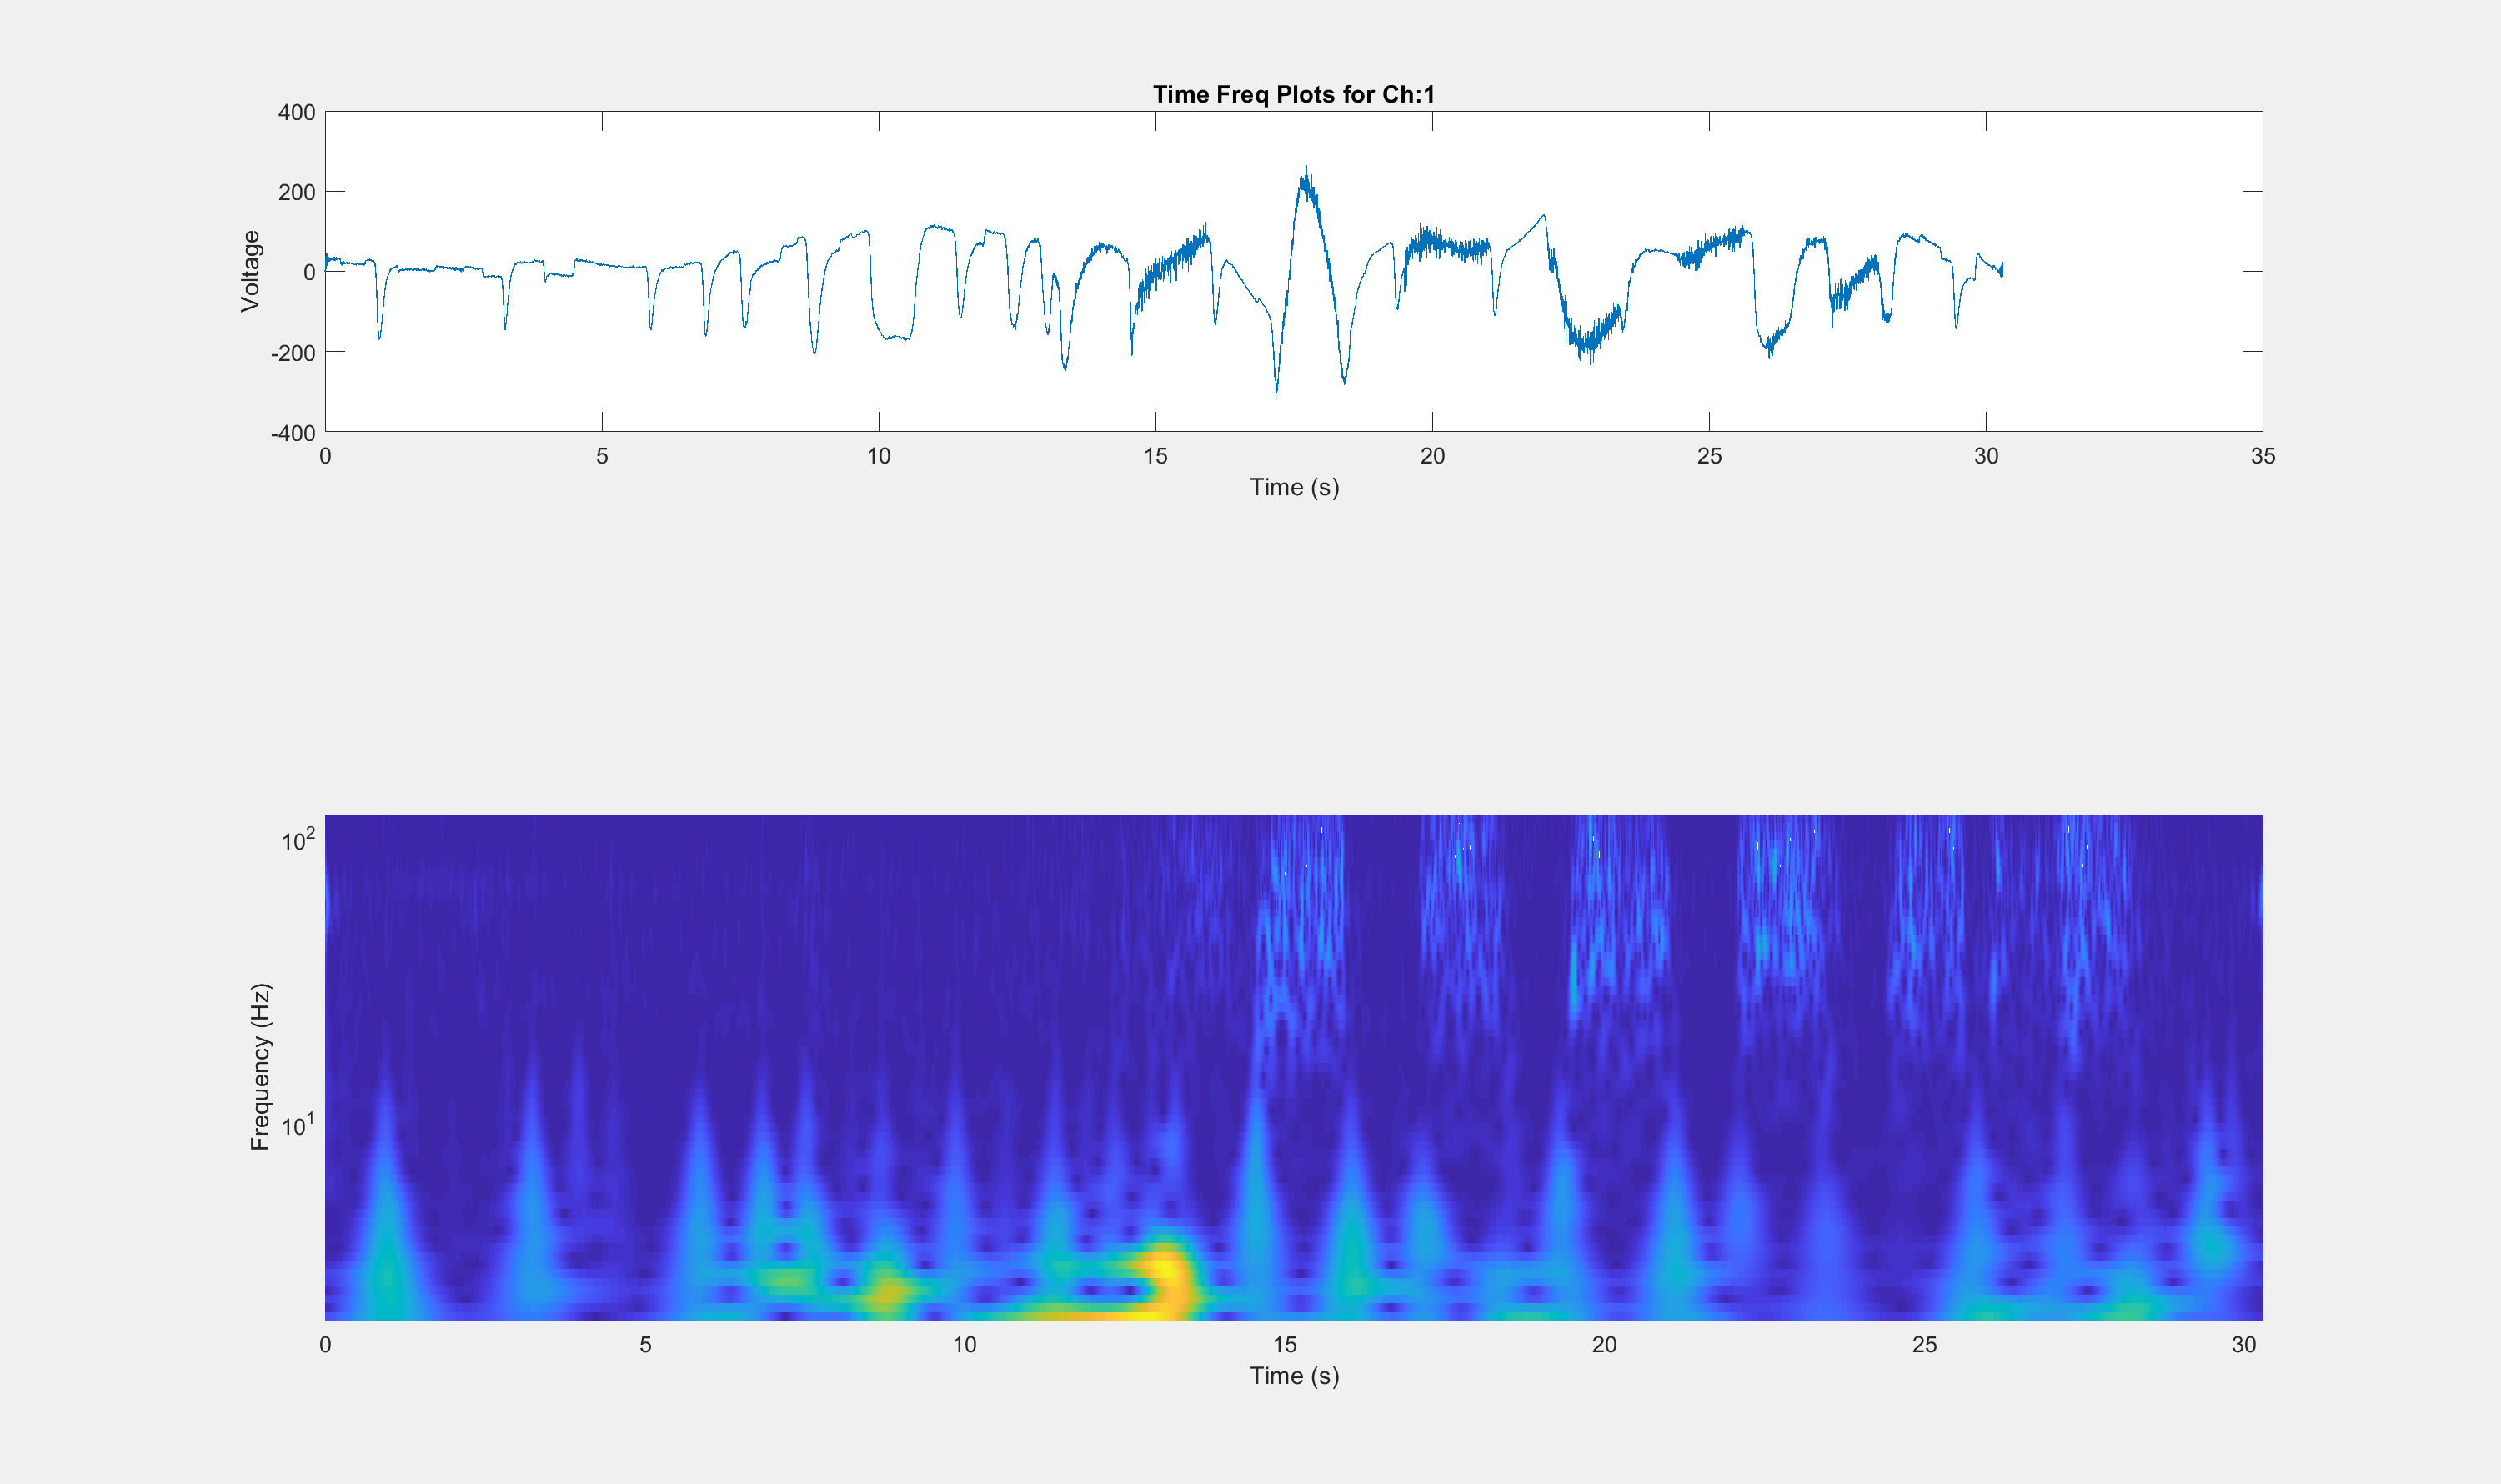

[cfs,frq] = cwt(double(EEG.data(channel,:)),EEG.srate,'FrequencyLimits',[2 120]);
tms = (0:numel(double(EEG.data(channel,:)))-1)/EEG.srate;

figure
set(gcf,'Visible','on','WindowState','maximized') % This pops out the figure for easier viewing
subplot(3,1,1)
plot(EEG.timessec, EEG.data(channel,:)); ylabel('Voltage'); xlabel('Time (s)');
title(strcat('Time Freq Plots for Ch: ', num2str(channel)));
subplot(2,1,2)
surface(tms,frq,abs(cfs))
axis tight
shading flat
xlabel('Time (s)')
ylabel('Frequency (Hz)')
set(gca,'yscale','log')

If we're looking the whole long data set (not just a minute or so), then we might need to break things up. Mostly we'll do this by epoching and looking at the markers, but we can take a peek here.

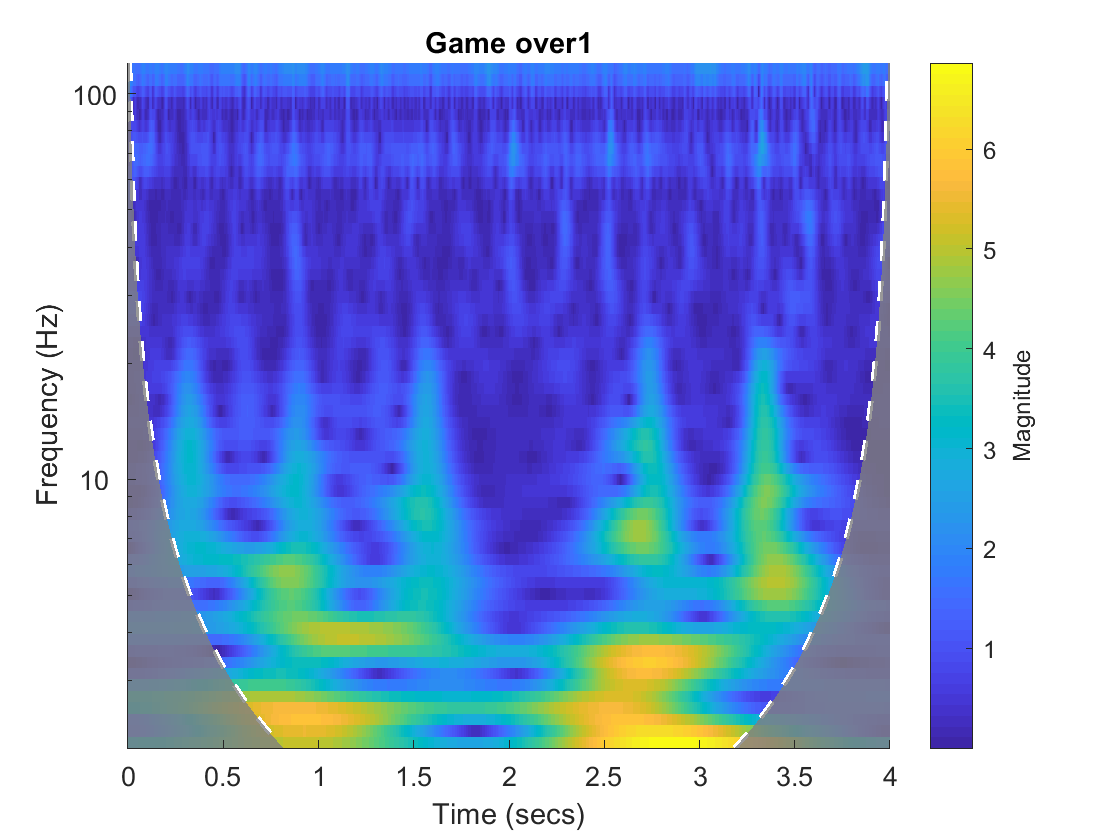

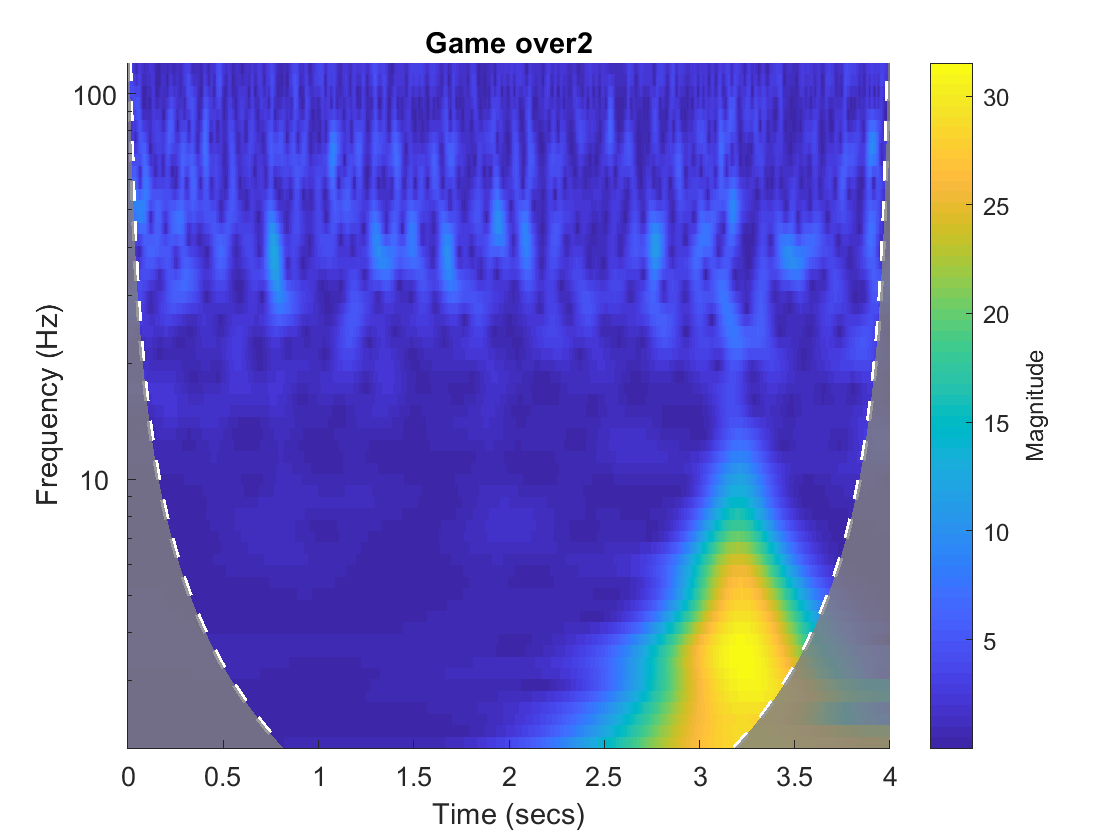

manualtimestampsforGameOver = [ (8*60)+25, (11*60)+50, (14*60)+55];
manualtimestampsforBadDrop = [(2*60)+49, (7*60)+48];

secondsofinterest = manualtimestampsforBadDrop;
timepointsofinterest = secondsofinterest.*EEG.srate;
secondsofinterestbuffertimepoints = [-1 3].*EEG.srate;

for i = 1:length(timepointsofinterest)
    offset = timepointsofinterest(i);
    figure; cwt(double(EEG.data(channel,(secondsofinterestbuffertimepoints(1)+offset): (secondsofinterestbuffertimepoints(2)+offset))),EEG.srate,'FrequencyLimits',[2 120]);
    %caxis([0 40])
    title(strcat('Game over', num2str(i)))
end

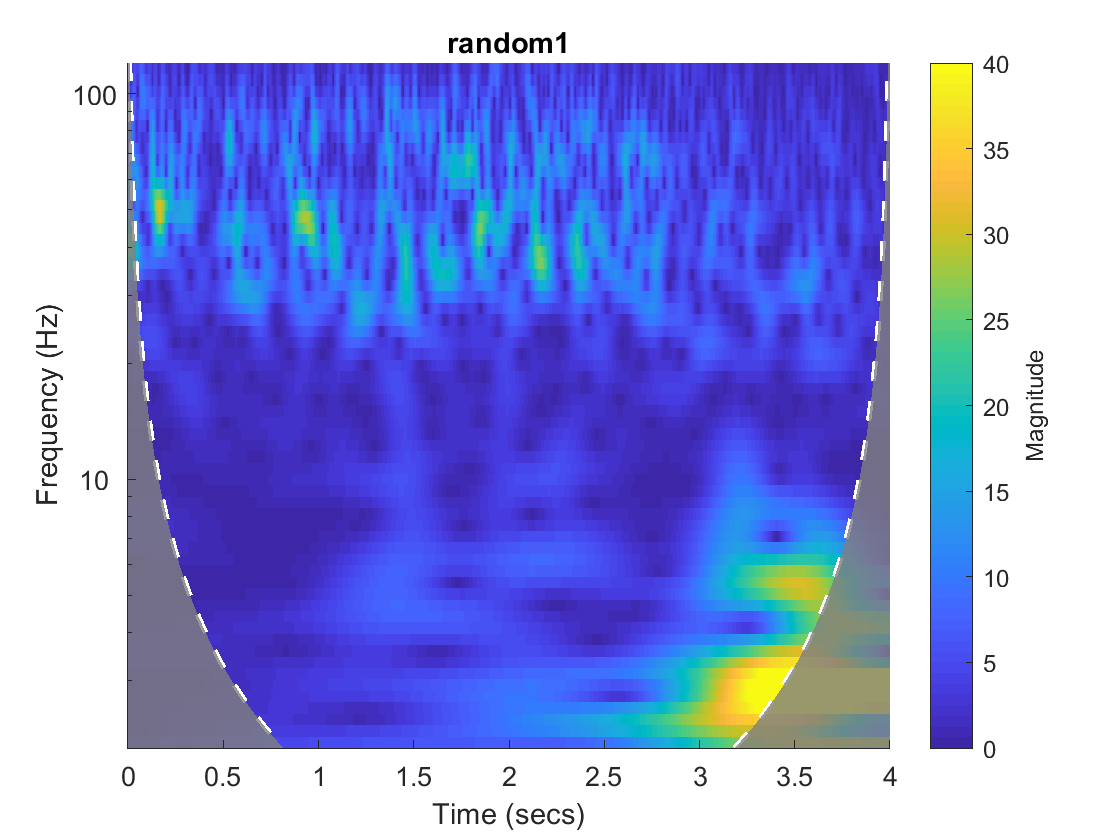

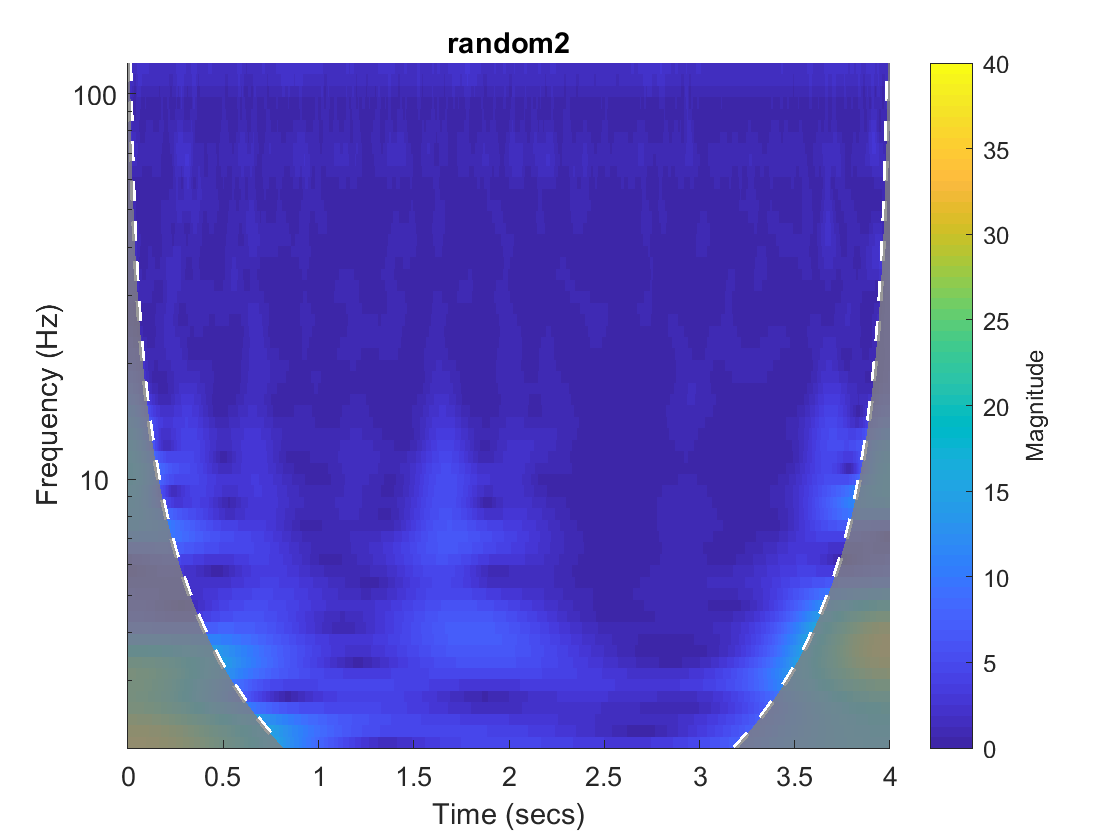


% Note: game over happens at about 1 second mark here
for i = 1:length(timepointsofinterest)
    offset = randi(EEG.pnts-4000)+2000;
    figure; cwt(double(EEG.data(channel,(secondsofinterestbuffertimepoints(1)+offset): (secondsofinterestbuffertimepoints(2)+offset))),EEG.srate,'FrequencyLimits',[2 120]);
    caxis([0 40])
    title(strcat('random', num2str(i)))
end


%[cfs,f] = cwt(double(EEG.data(channel,:)),EEG.srate);

Notes for next time: 

Figure out how to do stats for cwt to compare multiple instances of events